# VAR models

VAR stands for vector autoregression. To understand what this means, let us first look at a simple univariate (i.e. only one dependent or endogenous varaible) autoregressive (AR) model of the form


$$y_t = a_1y_{t-1}+e_t$$


In this model, the current value of variable $y$ depends on its first lag, where $a_1$ denotes its parameter coefficient  and the subscript refers to its lag. Since the model contains only one lagged alue the model is called autoregressive of order one, short AR(1), but you can easily increase the order to $p$ by adding more lags, which resutls in an AR(p). The error term $e_t$ is assumed to be normally distributed with mean zero and variance $\sigma^2$.

## Model and data

For this illustration we will be using the data we obtained in the previous script, it contains a timetable called economicDataTimetable with 3 variables namely: *fixed investment, disposable income and consumption expenditures* in billions of Rands from 2005Q1 to 2022Q4, 72 observations are used for inference. This has been stored in a .mat file and can be loaded from the editor into the workspace:

load Data\webinarData.mat

## Interactive modeling of VAR

The econometric modeler app is a MATLAB application that can be used for many econometric tasks such as testing, estimating and evaluating models. It can be started with either the command below, or with the button in the App gallery.

Alternatively, you can run **the same process** programatically as follows:

% Transforming the timeseries 
economicDataTimetable{2:end, :} = diff(log(economicDataTimetable{:,:})); % You can also do this using ret2tick(data, Method = 'Continuous')   
economicDataTimetable = economicDataTimetable(2:end, :);

Basically, it would be possible to proceed without any further transformation of the data. However, it is good practise to multiply log-differenced data by 100 so that, for example, the value 1% is indicated by 1 and not by 0.01.

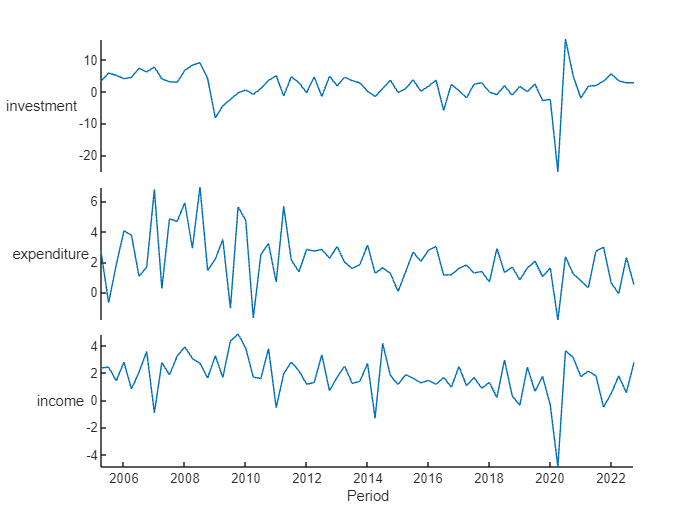

economicDataTimetable{:,:} = economicDataTimetable{:,:}*100;
figure;
stackedplot(economicDataTimetable)

## Stationarity

Before you estimate such a model you should always check if the time series you analyse are stationary, i.e. their means and variances are constant over time and do not show any trending behaviour. If you estimate models with non-stationary data you will get incorrect test statistics which might lead you to choose the wrong model.

There is a series of statistical tests like the Dickey-Fuller, KPSS, or the Phillips-Perron test to check whether a series is stationary. Both statistical and visual tests have their drawbacks and you should always be careful with those approaches, but they are an important part of every time series analysis. Additionally, you might want to check what the economic literature has to say about the stationarity of particular time series like, e.g., GDP, interest rates or inflation. This approach is particularly useful if you want to determine whether a series **trend or difference stationary**, which must be treated a bit differently.

At this point it should be mentioned that even if two time series are not stationary, a special combination of them can still be stationary. This phenomenon is called *cointegration* and so-called [**(vector) error correction models (VECM**](https://www.mathworks.com/help/econ/vecm.html)**)** can be used to analyse it. For example, this approach can significantly improve the results of an analysis of variables with known equilibrium relationships.

As an example, let's take a [kpsstest](https://www.mathworks.com/help/econ/kpsstest.html?s_tid=doc_ta)

[h,pValue,stat,cValue] = kpsstest(economicDataTimetable.income)

h = logical
   0


pValue = 0.1000

stat = 0.0497

cValue = 0.1460

## Vector autoregressive models

Regressing a macroeconomic variable solely on its own lags like in an AR(p) model might be a quite restrictive approach. Usually, it is more appropriate to assume that there are further factors that drive a process. This idea is captured by models which contain lagged values of the dependent variable as well as contemporaneous and lagged values of other, i.e. exogenous, variables. Again, these exogenous variables should be stationary. For an endogenous variable $y_t$ and an exogenous variable $x_t$ such an *autoregressive distributed lag* model can be written as:


$$y_t = a_1y_{t-1}+b_0x_t+b_1x_{t-1}+e_t$$


In this model $a_1%$ and $e_t$ are defined as above and $b_0$ and $b_1$ are the coefficients of the contemporaneous and lagged value of the exogenous variable, respectively.

The forecasting performance of such a model is likely to be better than for a simple AR model. However, if the exogenous variable depends on lagged values of the endogenous variable it would mean that $x_{x}$ is endogenous too and there is further space to improve our forecasts. At this point the VAR approach comes in. A simple VAR model can be written as


$$\left( {\begin{array}{c}
    y_{1t} \\ y_{2t} 
  \end{array} } \right) = \left[ {\begin{array}{cc}
    a_{11} & a_{12} \\
    a_{21} & a_{22} \\
  \end{array} } \right]\left( {\begin{array}{c}
    y_{1t-1} \\ y_{2t-1} 
  \end{array} } \right)+\left( {\begin{array}{c}
    \epsilon_{1t} \\ \epsilon_{2t} 
  \end{array} } \right)$$


or more compactly:


$$y_t=A_1y_{t-1}+\epsilon_t$$


where $y_t=\left( {\begin{array}{c}
    y_{1t} \\ y_{2t} 
  \end{array} } \right) $, $A_1=\left[ {\begin{array}{cc}    a_{11} & a_{12} \\    a_{21} & a_{22} \\  \end{array} } \right]$ and $\epsilon_t = \left( {\begin{array}{c}    \epsilon_{1t} \\ \epsilon_{2t}   \end{array} } \right)$.

Basically, such a model implies that *everything depends on everything*. But as can be seen from this formulation, each row can be written as a separate equation, so that $y_{1t}=a_{11}y_{1t-1}+a_{12}y_{2t-1}+\epsilon_{1t}$ and $y_{2t}=a_{21}y_{1t-1}+a_{22}y_{2t-1}+\epsilon_{2t}$. Hence, the VAR model can be rewritten as a series of individual models as described above. In fact, it is possible to estimate VAR models by estimating each equation separately.

Looking a bit closer at the single equations you will notice, that there appear no contemporaneous values on the right-hand side (*rhs*) of the VAR model. However, information about contemporaneous relations can be found in the so-called *variance-covariance matrix* $\Sigma$. It contains the variances of the endogenous variable on its diagonal elements and covariances of the errors on the off-diagonal elements. the covariances contain information about contemporaneous effects between the variables. Like the error variance $\sigma^2$ in a single equation model, $\Sigma$ is essential for the calculation of test statistics and confidence intervals.

The covariance matrices of standard VAR models are *symmetric*. This reflects the idea that the relations between the endogenous variables only reflect correlations and do not allow to make statements about causal relationships, since the effects are the same in each direction. This is the reason why this model is said to be not uniquely *identified*.

Contemporaneous causality or, more precisely, the structural relationships between the variables is analysed in the context of so-called *structural* VAR (**SVAR**) models, which impose special restrictions on the covariance matrix – and depending on the model on other matrices as well – so that the system is identified. his means that there is only one unique solution for the model and it is clear, how the causalities work. The drawback of this approach is that it depends on the assumptions made. 

### Estimation

We calculate frequentist VAR estimates using the standard formula $(xx' )^{-1}x'y$ to obtain a benchmark for the Bayesian estimator. The parameters are obtained by OLS:

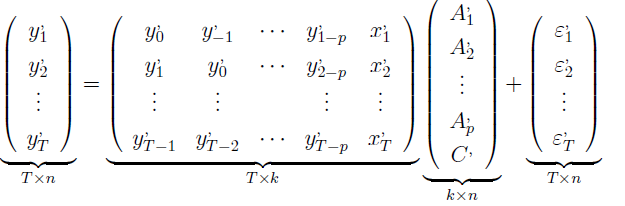


$$Y = XA+\varepsilon$$


y = economicDataTimetable{3:end,:};
x = [economicDataTimetable{2:end-1, 1:3} economicDataTimetable{1:end-2, 1:3} ones(size(y,1), 1)];

From this form, we can estimate the coefficients as follows:


$$\hat A=(X'X)^{-1}X'Y$$


A_freq = x\y % A_freq = (x'*x)\(x'*y) This commands are equivalent, the first is numerically more stable 

A_freq =    -0.0226    0.0059   -0.0082
    0.4427   -0.1183    0.1302
   -0.1229    0.3225   -0.0591
    0.1249    0.0744   -0.0709
    0.1495   -0.0217    0.1522
   -0.7752   -0.0212    0.0585
    1.8691    1.7621    1.2799


And then calculate the error and the innovations matrix:

Epsilon = y - x*A_freq;
Sigma = (Epsilon'*Epsilon)/(size(y,1)) % The normalization component sometimes is different, you can also find Sigma = (Epsilon'*Epsilon)/(size(y,1) - size(A_freq, 1) - 1)

Sigma =    22.7676    2.8734    3.0462
    2.8734    2.5673    0.8121
    3.0462    0.8121    2.1243


Alternatively, the same problem can be estimated using the varm function in MATLAB, with the exact same results. The following function creates a model of the following type:


$$y_t=c+A_1y_{t-1}+A_2y_{t-2}+\ldots+A_py_{t-p}+Bx_t+\delta t + \varepsilon_t \qquad \rightarrow \qquad Mdl = varm(numseries, numlags)$$


Mdl = varm(3, 1);
EstMdl = estimate(Mdl, economicDataTimetable{:,:});
summarize(EstMdl)

 
   AR-Stationary 3-Dimensional VAR(1) Model
 
    Effective Sample Size: 70
    Number of Estimated Parameters: 12
    LogLikelihood: -460.982
    AIC: 945.964
    BIC: 972.946
 
                     Value       StandardError    TStatistic      PValue  
                   __________    _____________    __________    __________

    Constant(1)         1.283        1.0765          1.1918        0.23333
    Constant(2)        1.7703       0.36775          4.8139     1.4801e-06
    Constant(3)        1.5834       0.32944          4.8063     1.5373e-06
    AR{1}(1,1)     -0.0039399       0.13456        -0.02928        0.97664
    AR{1}(2,1)      0.0043886      0.045966        0.095474        0.92394
    AR{1}(3,1)     -0.0044485      0.0

And $\Sigma$ is calculated by $\frac{\varepsilon\varepsilon}{T }$

EstMdl.Covariance

ans =    23.7354    2.7733    2.9222
    2.7733    2.7698    0.6848
    2.9222    0.6848    2.2227


### Generate Forecasts 

Generate forecasts and approximate 95% forecast intervals from the estimated EstMdl(VAR) model for the next four years (16 quarters). For convenience, use the entire series as a presample for the forecasts. The forecast function discards all specified presample observations except for the required final two observations.

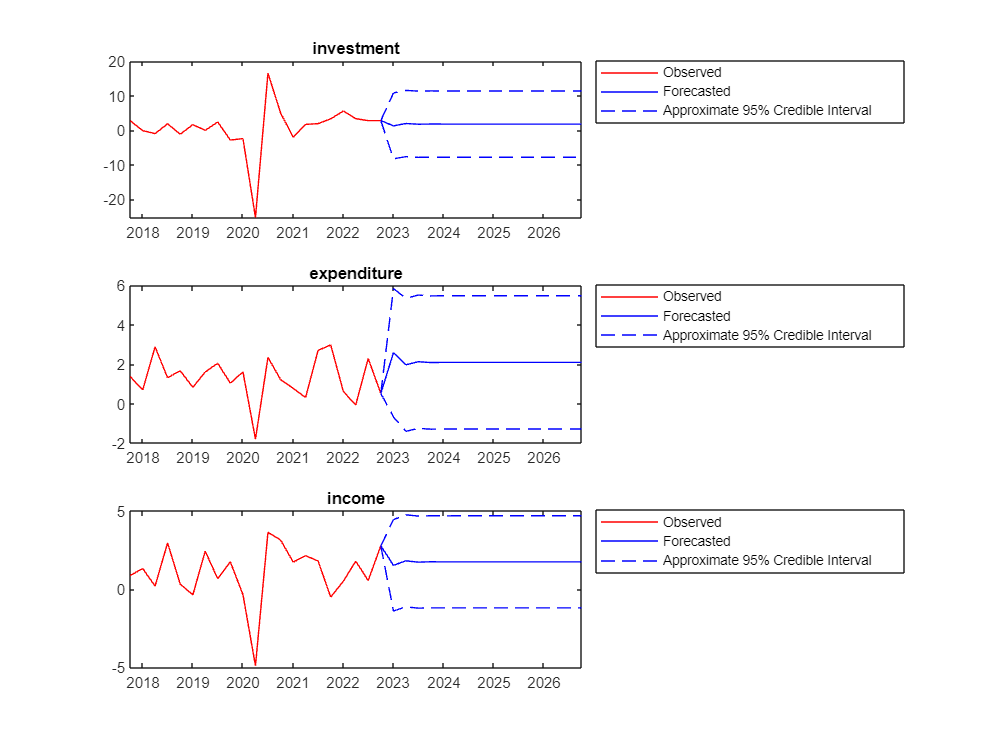

Y = economicDataTimetable{:,:};
numperiods = 16;
cols = {'investment', 'expenditure', 'income'};
[YF,YFSt] = forecast(EstMdl, numperiods, Y);
YFSt = cell2mat(cellfun(@(x)sqrt(diag(x)'),YFSt, ...
    UniformOutput=false));
fh = economicDataTimetable.Period(end) + calquarters(0:numperiods);

figure('Position',[100 100 800 600]);
for j = 1:3
subplot(3,1,j)
plot(economicDataTimetable.Period(end-20:end), economicDataTimetable{end - 20:end,j},'r',...
    fh, [economicDataTimetable{end,j}; YF(:,j)],'b',...
    fh, [economicDataTimetable{end,j}; YF(:,j) + 1.96*YFSt(:,j)],'b--',...
    fh, [economicDataTimetable{end,j}; YF(:,j) - 1.96*YFSt(:,j)],'b--');
legend("Observed","Forecasted","Approximate 95% Credible Interval",'Location','bestoutside')
title(cols{j})
end

*Note: these are the transformed time series(log differenced)*

### Conduct Causality Analysis

Determine whether series in the system Granger-cause the other series by conducting 1-step, Granger-causality tests. Pass the estimated EstMdl model to gctest.

gctest(EstMdl)

                    H0                         Decision         Distribution    Statistic     PValue     CriticalValue
    __________________________________    __________________    ____________    _________    ________    _____________

    "Exclude lagged Y2 in Y1 equation"    "Cannot reject H0"     "Chi2(1)"        0.60241     0.43766       3.8415    
    "Exclude lagged Y3 in Y1 equation"    "Cannot reject H0"     "Chi2(1)"       0.018594     0.89154       3.8415    
    "Exclude lagged Y1 in Y2 equation"    "Cannot reject H0"     "Chi2(1)"      0.0085944     0.92614       3.8415    
    "Exclude lagged Y3 in Y2 equation"    "Reject H0"            "Chi2(1)"         4.1534    0.041551       3.8415    
    "Exclude lagged Y1 in Y3 equation"    "Cannot reject H0"     "Chi2(1)"       

ans = 6×1 logical array
   0
   0
   0
   1
   0
   0


The null hypothesis of the 1-step leave-one-out Granger-causality test is that a series does not 1-step Granger-cause another series, conditioned on all other series being present in the system. This test shows:

- a change in expenditure causes a change in investment

- a change in income causes a change in investment 

- a change in invesment causes a change in income 

- a change in expenditure does not cause a change in income 

- a change in investment causes a change in income 

- a change in income causes a change in expenditure